# **	Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Topic 4 part 2: exercise 02 - Fourier Descriptors

The objective of the practice is to calculate the Fourier descriptors of all the objects in an image and to use only the most significant ones of each object to reconstruct them.

## Question 1) Fourier descriptor

- Using the `fourier_descriptors` function (step 5), obtain the Fourier descriptors of each of the labelled objects.

- Obtain the reconstructed contours of the labelled objects from Fourier inverse descriptors by using the `fourier_inv_descriptors` function using 10% of the descriptors for reconstruction. Plot the recovered contour.

- Reduce the number of descriptors used for reconstruction to 5% and 2% and draw conclusions.

Step 1) Read Image

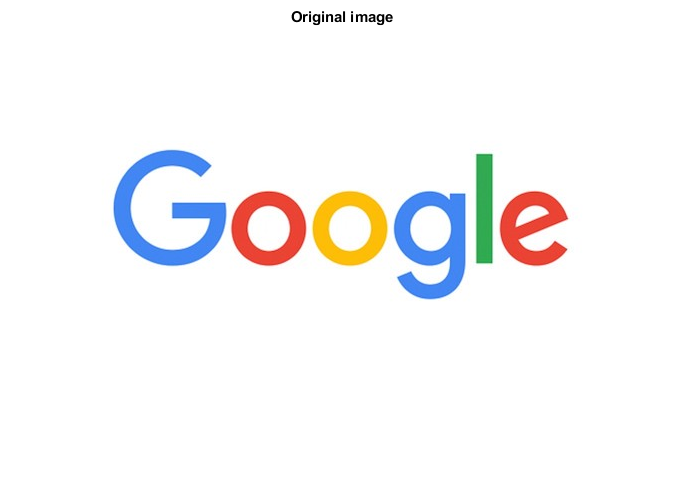

    close all
    clear all

    imgOriginal = imread('C:\Users\santi\Downloads\google.jpg');
    figure;
    imshow(imgOriginal);
    title('Original image');

Step 2) Threshold the Image

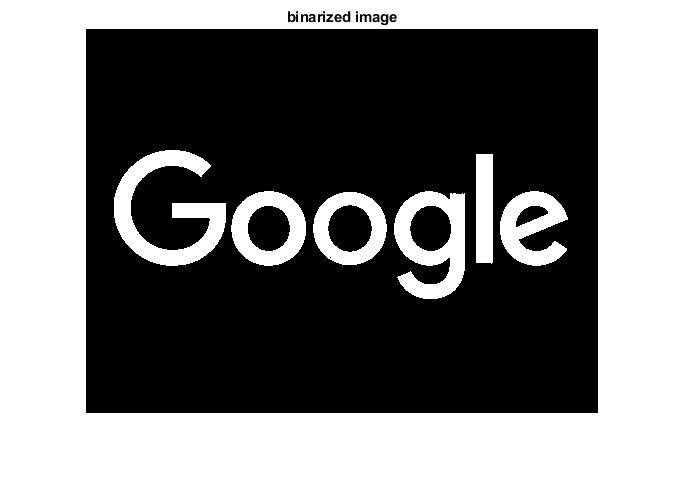

    if size(imgOriginal,3) == 3
        imgOriginal = rgb2gray(imgOriginal); 
    end
    imgBW = imbinarize(imgOriginal);
    imgBW = imcomplement(imgBW);
    
    figure;
    imshow(imgBW);
    title('binarized image');

Step 4) Find the Boundaries

    [B,L] = bwboundaries(imgBW,'noholes');
    figure
    imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
    hold on
    for k = 1:length(B)
       boundary = B{k};
       plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 4);
    end  

Step 5)  Fourier descriptors 

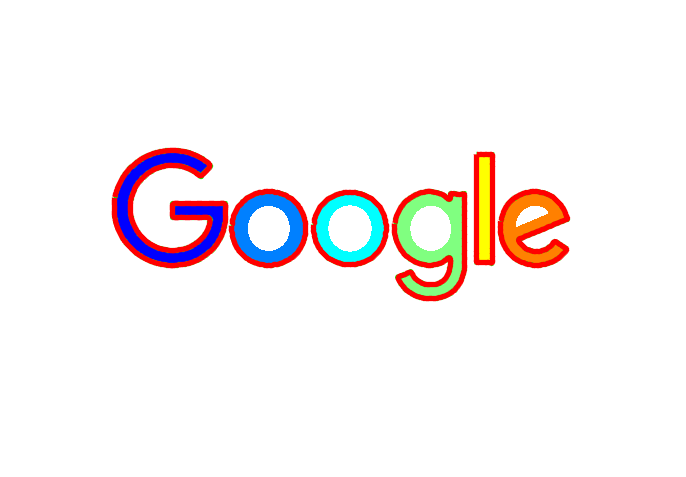

     
    for k = 1:length(B)
       boundary = B{k};
       % fourier_descriptors()
       fft=fourier_descriptors(boundary);
       % fourier_inv_descriptors()
       inversa_fft=fourier_inv_descriptors(fft,10);
       % plot recovered boundary
       for k = 1:length(inversa_fft)
            %boundary = inversa_fft{k};
            plot(inversa_fft(:,2), inversa_fft(:,1), 'r', 'LineWidth', 4);
       end  
    end   